%inputID = input('Enter your id in Decimal: ', 's');
%inputID = 19;
%inputIDinNum = str2num(inputID);
%inputIDinBin = fliplr(de2bi(inputIDinNum))
inputIDinBin = fliplr(de2bi(19))

inputIDinBin =      1     0     0     1     1


data = inputIDinBin

data =      1     0     0     1     1


j=0;
b = zeros(1, length(data))

b =      0     0     0     0     0


for i=1:length(data)
    if data(i)==1
        b(i)=0
    else
        j=j+1;
        if mod(j,2)==0
            b(i)=-1
        else
            b(i)=+1
        end
    end
end

b =      0     0     0     0     0


b =      0     1     0     0     0


b =      0     1    -1     0     0


b =      0     1    -1     0     0


b =      0     1    -1     0     0


if b(end)==1
    b(1,end+1)=1
else if b(end)==-1
        b(1,end+1)=-1
else
    b(1,end+1)=0
end
    
end

b =      0     1    -1     0     0     0


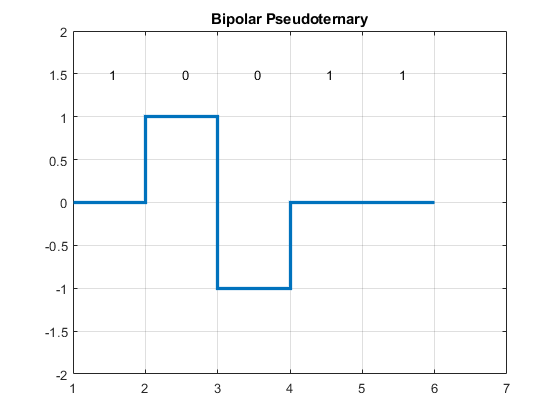

stairs(b,'LineWidth',2.5)
axis([1 7 -2 2]);
for a=1:length(data)
        text(a+0.5,1.5,num2str(data(a)))
end
title('Bipolar Pseudoternary')
grid on;